# BANG-BANG control of a pure inertia.

## Data:

global J usat tol

Inertia $J\,(Kgm^2)$:

J=1000;

Saturation $\bar{u}\,(Nm)$:

usat=0.5;

Initial position $\theta_0\,(rad)$:

x0=1;

Initial angular rate $\dot\theta_0\,(rad/s)$:

xdot0=-1;

Tolerance on the position $\delta\theta\,(rad)$ (to avoid "chattering" around $0$ at the end of the trajectory):

tol=1e-5;

## Computation of the mininal final time $$t_f$ and commutation time $t_c$ (from slide 39 and 40)

if x0+J/2/usat*xdot0*abs(xdot0)>0
    tf=(xdot0+2*sqrt(xdot0^2/2+x0*usat/J))*J/usat;
    tc=(xdot0+sqrt(xdot0^2/2+x0*usat/J))*J/usat;
else
    tf=(-xdot0+2*sqrt(xdot0^2/2-x0*usat/J))*J/usat;
    tc=(-xdot0+sqrt(xdot0^2/2-x0*usat/J))*J/usat;
end
tf

tf = 4.8270e+03

tc

tc = 3.4135e+03

## Simulation

The Simulink file `bangbang.slx:`

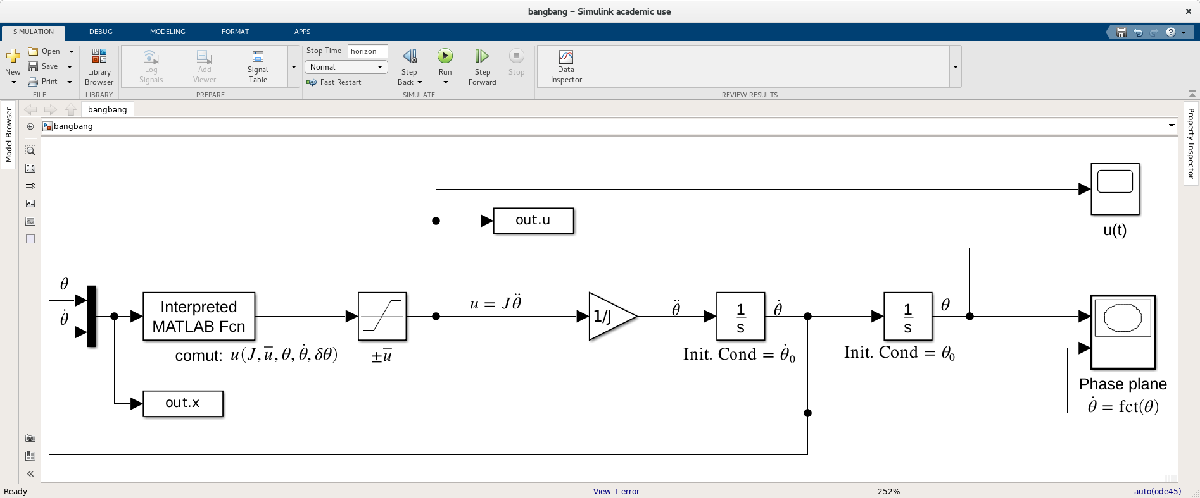

% Simulation stop time:
horizon=1.5*tf;
% Simulation:
bangbang
out=sim('bangbang');

Plot the results:

The control signal $u(t)$.

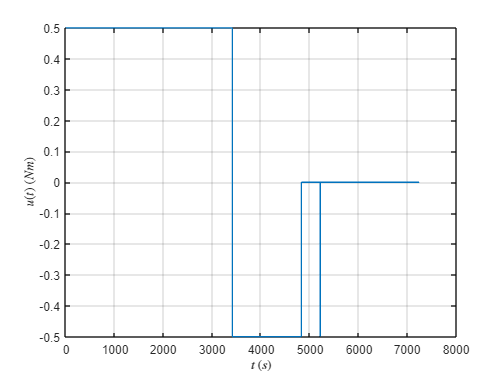

figure
plot(out.u.time,out.u.signals.values);
xlabel('$t\,(s)$','Interpreter','Latex')
ylabel('$u(t)\,(Nm)$','Interpreter','Latex');
grid

**Comments:**

- one can check the values of $t_c$ and $t_f$,

- at the time $t\approx 5200\,s$, one can see a "chattering" behavior: due to numerical errors ( $\dot\theta$ is not excatly equal to $0$), there is a drift on $\theta$ and the control becomes active if $\theta\ge \delta\theta$.

The state trajectory in the phase plane:

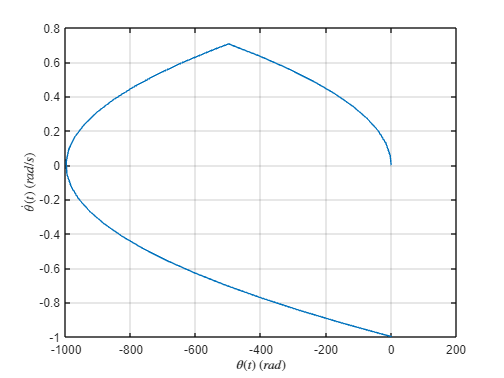

figure
plot(out.x.signals.values(:,1),out.x.signals.values(:,2));
xlabel('$\theta(t)\,(rad)$','Interpreter','Latex')
ylabel('$\dot\theta(t)\,(rad/s)$','Interpreter','Latex');
grid

**Comments:**

- we can note on the optimal trajectory the maximal angular deviation is $-1000\,rad$!!!. Indeed the initial angular rate $|\dot\theta_0|$ is very big for a spacecraft and not representative of a space application. So it takes a very long time to slow down the spacecraft considering the actuator saturation $\bar u$. A more realistic simulation can be done with $\dot\theta_0=0.01\,(rad/s)$.